# Task 3.1 - KKT Conditions

## Graphical solution

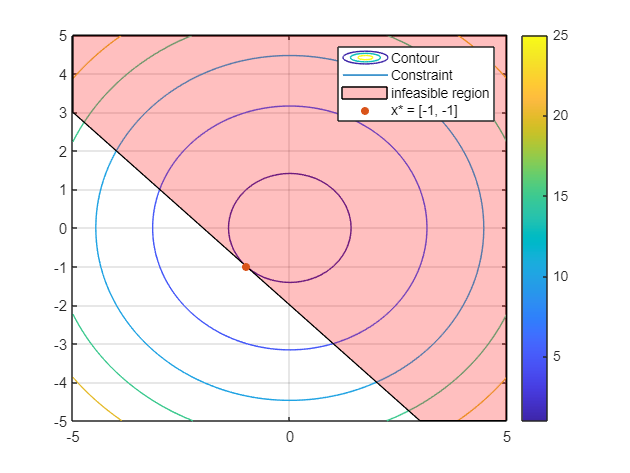

f = @(x1, x2) 1/2*(x1.^2 + x2.^2);
A = [1 1];
b = -2;

l = @(x1, x2) A*[x1;x2] - b;

cont = fcontour(f);
cont.LevelList = [1, cont.LevelList];
hold on
grid on
fimplicit(l)
fill([-5 3 5 5 -5],[3 -5 -5 5 5], 'r', "FaceAlpha", 0.25);
plot(-1, -1, '.', 'MarkerSize', 16)
legend("Contour", "Constraint", "infeasible region", "x* = [-1, -1]")
colorbar
hold off

## Analytical solution

First we build the Lagrangian:


$$L = \frac{1}{2}(x_1^2+x_2^2)+\mu(x_1+x_2+2)$$


From KKT conditions we get that the gradient of the Lagrangian has to be 0.


$$\nabla L = [x_1+\mu \ x_2+\mu] \stackrel{!}{=} 0 \ \\ \rightarrow \ x^* = [-\mu \ -\mu]$$
 

The complementary condition requires


$$\mu(x_1+x_2+2) = 0$$



$$\mu = 0 \vee x_1+x_2 = -2$$


If $\mu$ was equal to zero, the solution would be $[0 \ 0]$, which is infeasible, so:


$$-2\mu = -2 \rightarrow \mu = 1$$



$$x^* = [-1 \ -1]^T$$


## Numerical solution

optimoptions("fmincon", "SpecifyObjectiveGradient", true);

sol = fmincon(@cost_fun_grad, [0; 0], A, b)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol =    -1.0000
   -1.0000


function [fv, grad] = cost_fun_grad(x)

fv = 1/2*(x'*x);

grad = x;

end